# Macm 203 Assignment 6

April Nguyen

## Part A: Denoising smooth images

Consider the following smooth grayscale image of size nxn:

I=(1+cos(2*pi*(1:n)/n)'*sin(2*pi*(1:n)/n))/2;

Add Gaussian noise. Now apply mean filtering and median filtering to your noisy image. Which gives better results? Explain visually and using immse(). Apply a suitable structuring element and boundary conditions.

Add Salt & Pepper noise. Now apply mean filtering and median filtering to your noisy image. Which gives better results? Explain visually and using immse(). Apply a suitable structuring element and boundary conditions.

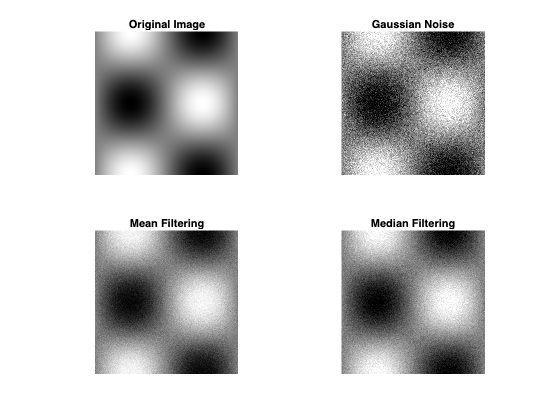

clc,clf,clearvars;
n = 1000;
I = (1+cos(2*pi*(1:n)/n)'*sin(2*pi*(1:n)/n))/2;

% Add Gaussian noise
sigma = 1e-1;
G = imnoise(I,'gaussian',0,sigma^2);

% Apply mean filtering to G with mirror boundary conditions
filterSize = 3;
Gmeanfilter = imfilter(G,fspecial('average', filterSize), 'symmetric');

% Apply median filtering to G with mirror boundary conditions
Gmedfilter = medfilt2(G,'symmetric');

% Display the images
clf;
subplot(2,2,1)
imshow(I)
title('Original Image')
subplot(2,2,2)
imshow(G)
title('Gaussian Noise')
subplot(2,2,3)
imshow(Gmeanfilter)
title('Mean Filtering')
subplot(2,2,4)
imshow(Gmedfilter)
title('Median Filtering')


% Mean vs Median Filtering
immse(I,Gmeanfilter)

ans = 0.0011

immse(I,Gmedfilter)

ans = 0.0016

Visually, the mean filtering looks less noisy than the median filtering, when comparing it to the original image. Calculating the mean-squared error with immse(), we also see that the difference between the original image and the mean filtered image, is smaller than the difference between the original image and the median filtered image (0.0012 < 0.0016). So the original image and the mean filtered image are more similar than the median filtered image.

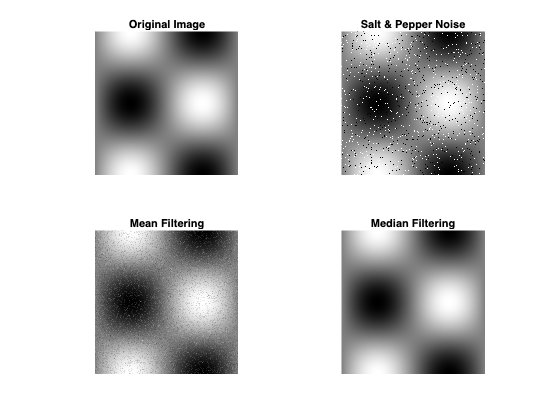

clc,clf;

n = 1000;
I = (1+cos(2*pi*(1:n)/n)'*sin(2*pi*(1:n)/n))/2;

% Add Salt & Pepper noise to the original image
density = 0.05;
SP = imnoise(I,'salt & pepper', density);

% Apply mean filtering to SP with mirror boundary conditions
filterSize = 3;
SPmeanfilter = imfilter(SP,fspecial('average', filterSize),'symmetric');

% Apply median filtering to SP with mirror boundary conditions
SPmedfilter = medfilt2(SP,'symmetric');

% Display the images
clf;
subplot(2,2,1)
imshow(I)
title('Original Image')
subplot(2,2,2)
imshow(SP)
title('Salt & Pepper Noise')
subplot(2,2,3)
imshow(SPmeanfilter)
title('Mean Filtering')
subplot(2,2,4)
imshow(SPmedfilter)
title('Median Filtering')


% Mean vs Median Filtering
immse(I,SPmeanfilter)

ans = 0.0019

immse(I,SPmedfilter)

ans = 6.9014e-07

Visually, the median filtering gives better results, with the median filtered image looking more similar to the original image than the mean filtering does. This is confirmed by the immse() of median being smaller than of mean, so the mean-squared error of the original and median is smaller than that of the original and the mean. 

## Part B: Denoising nonsmooth images

clc,clf,clearvars;
textImage = im2double(imread('text.png'));

% Add gaussian noise
sigma = 1e-1;
tIGaussian = imnoise(textImage,'gaussian',0,sigma^2);

% Apply mean filtering
filterSize = 3;
tIMeanFilter = imfilter(tIGaussian,fspecial('average',filterSize),'symmetric');

% Apply median filtering
tIMedFilter = medfilt2(tIGaussian,'symmetric');

% Mean vs median filtering
immse(textImage,tIMeanFilter)

ans = 0.0168

immse(textImage,tIMedFilter)

ans = 0.0089

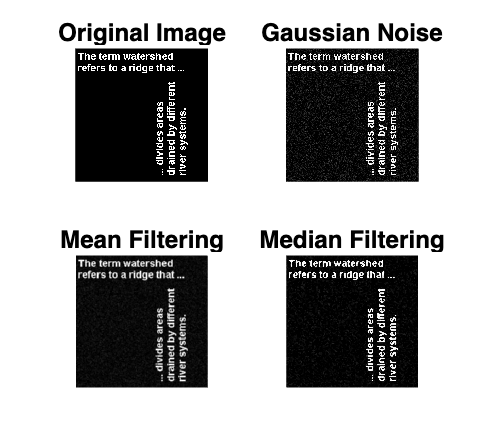

clf;
subplot(2,2,1)
imshow(textImage)
title('Original Image')
subplot(2,2,2)
imshow(tIGaussian)
title('Gaussian Noise')
subplot(2,2,3)
imshow(tIMeanFilter)
title('Mean Filtering')
subplot(2,2,4)
imshow(tIMedFilter)
title('Median Filtering')

By running immse() on the median and mean filtered images, we see that median filtering has the smaller mean-squared value when comparing to the original image. We also see visually that the output of mean filtering has changed the text colour from a stark white to a more muted gray-white colour.

% Add salt & pepper noise
clc,clf;
textImage = im2double(imread('text.png'));
density = 0.05;
tISP = imnoise(textImage,'salt & pepper',density);

% Apply mean filtering
filterSize = 3'

filterSize = 3

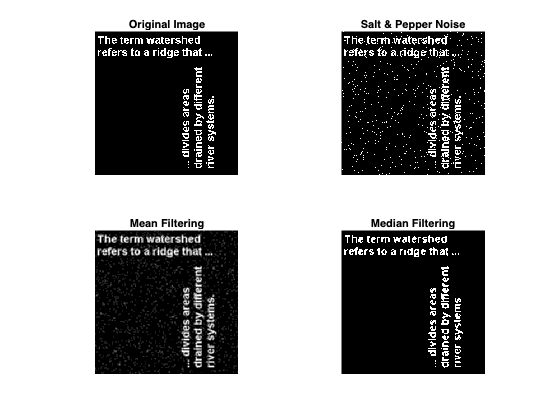

tISPMeanFilter = imfilter(tISP,fspecial('average',filterSize),'symmetric');

% Apply median filtering
tISPMedFilter = medfilt2(tISP,'symmetric');

clf;
subplot(2,2,1)
imshow(textImage)
title('Original Image')
subplot(2,2,2)
imshow(tISP)
title('Salt & Pepper Noise')
subplot(2,2,3)
imshow(tISPMeanFilter)
title('Mean Filtering')
subplot(2,2,4)
imshow(tISPMedFilter)
title('Median Filtering')


% Mean vs median filtering
immse(textImage,tISPMeanFilter)

ans = 0.0180

immse(textImage,tISPMedFilter)

ans = 0.0106

From immse(), median filtering produces better results as its mean-squared error of the original is smaller than the mean-squared error of mean and the original image. We also notice that the Mean Filtering appears to have left more of the white pixels compared to the median filtering.

## Part C: Image enhancement via ordered filters

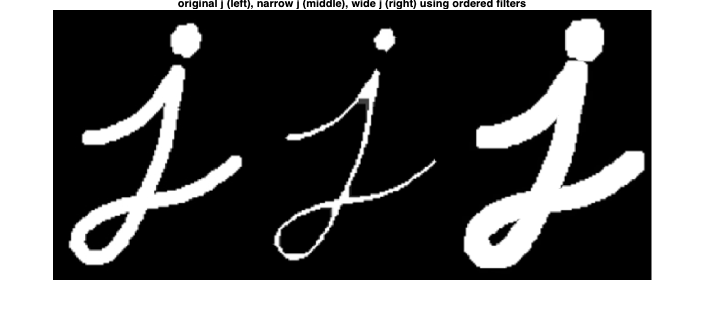

clearvars,clc,clf;
J = imread('letterj.jpg');

% Explore the use of ordered filters to make the letter wider and narrower
% You may wish to use the ordfilt2() command to simplify your coding task

% Makes j narrower
Jthin = J;
domainthin = ones(10,10);
orderthin = 1;
%for i=1:3
%    Jthin(:,:,i) = ordfilt2(Jthin(:,:,i),orderthin,domainthin);
%end
%imshow(Jthin)
Jthin = cat(3, ordfilt2(Jthin(:,:,1),orderthin,domainthin), ...
                ordfilt2(Jthin(:,:,2),orderthin,domainthin), ...
                ordfilt2(Jthin(:,:,3),orderthin,domainthin));
% Makes j wider
Jwide = J;
domainwide = ones(10,10);
orderwide = numel(domainwide);
%for i=1:3
%    Jwide(:,:,i) = ordfilt2(Jwide(:,:,i),orderwide,domainwide);
%end
Jwide = cat(3, ordfilt2(Jwide(:,:,1),orderwide,domainwide),...
                ordfilt2(Jwide(:,:,2),orderwide,domainwide),...
                ordfilt2(Jwide(:,:,3),orderwide,domainwide));

% Display the j's
montage({J,Jthin,Jwide})
title('original j (left), narrow j (middle), wide j (right) using ordered filters')